# Using ADI Transceiver Toolbox System Objects

We now look at how the Transceiver Toolbox system objects can be configured and used to stream data to and from the radio. Let us start with an example that uses ADALM-Pluto to stream data.

## adi.Pluto.Tx and adi.Pluto.Rx

Let us begin by instantiating the Pluto Tx system object. 

clear all;
plutoTx = adi.Pluto.Tx

plutoTx =   adi.Pluto.Tx with properties:

        CenterFrequency: 2.4000e+09
           SamplingRate: 3000000
            RFBandwidth: 3000000
    AttenuationChannel0: -30
           RFPortSelect: 'A'
     EnableCustomFilter: false
                    uri: 'ip:10.0.0.200'
        EnabledChannels: 1
             DataSource: 'DMA'
    EnableCyclicBuffers: false


Some of the properties of the plutoTx system object will seem straightforward. **AttenuationChannel0** applies the desired level of attenuation to the signal before it gets transmitted. **DataSource** is specified as either 'DMA', which specifies the host as the source of the data, or 'DDS', which specifies the DDS on the radio hardware as the source of the data. Let us first update the URI to the default IP address and select the DDS as the data source. The last statement in the code fragment below calls the transmitter system object and transmits the DDS waveform continuously. 

plutoTx.uri = 'ip:192.168.3.1';
plutoTx.AttenuationChannel0 = -10;
plutoTx.DataSource = 'DDS';
plutoTx.DDSFrequencies = repmat(5e5, 2, 2);
plutoTx();

## Capturing a Buffer

Now, let us instantiate the Pluto Rx system object, update the URI and configure the receiver to use manual gain control. 

plutoRx = adi.Pluto.Rx('uri','ip:192.168.3.1','GainControlModeChannel0','manual','GainChannel0',30)

plutoRx =   adi.Pluto.Rx with properties:

             CenterFrequency: 2.4000e+09
                SamplingRate: 3000000
                 RFBandwidth: 3000000
     GainControlModeChannel0: 'manual'
                GainChannel0: 30
                LoopbackMode: 0
    EnableQuadratureTracking: true
          EnableRFDCTracking: true
    EnableBasebandDCTracking: true
                RFPortSelect: 'A_BALANCED'
             SamplesPerFrame: 32768
          EnableCustomFilter: false
                         uri: 'ip:192.168.3.1'
             EnabledChannels: 1


Additionally, let us set the number of kernel buffers to 1 and grab a frame. 

plutoRx.kernelBuffersCount = 1; 
y = plutoRx();

You will notice that *y* is a 32768 element complex double column vector passed to MATLAB from iiod running on ADALM-Pluto. 

While most of the properties in the **plutoRx** MATLAB system object might seem straightforward, the properties SamplesPerFrame and kernelBuffersCount need some explanation. For RX when the operator (or step method) is called for the first time,  the buffers are created within the DMA on Pluto itself. By default 4 are created and start to be filled. The first buffer is returned once it is filled and the other will continue to fil. Together they form a  circular buffer and as soon as one is requested/pulled it frees up space for the next one. Therefore, you are guaranteed for the first 4 buffers to be contiguous. However, if you do not request/pull buffers fast  enough data can be dropped between buffers after the first 4. 

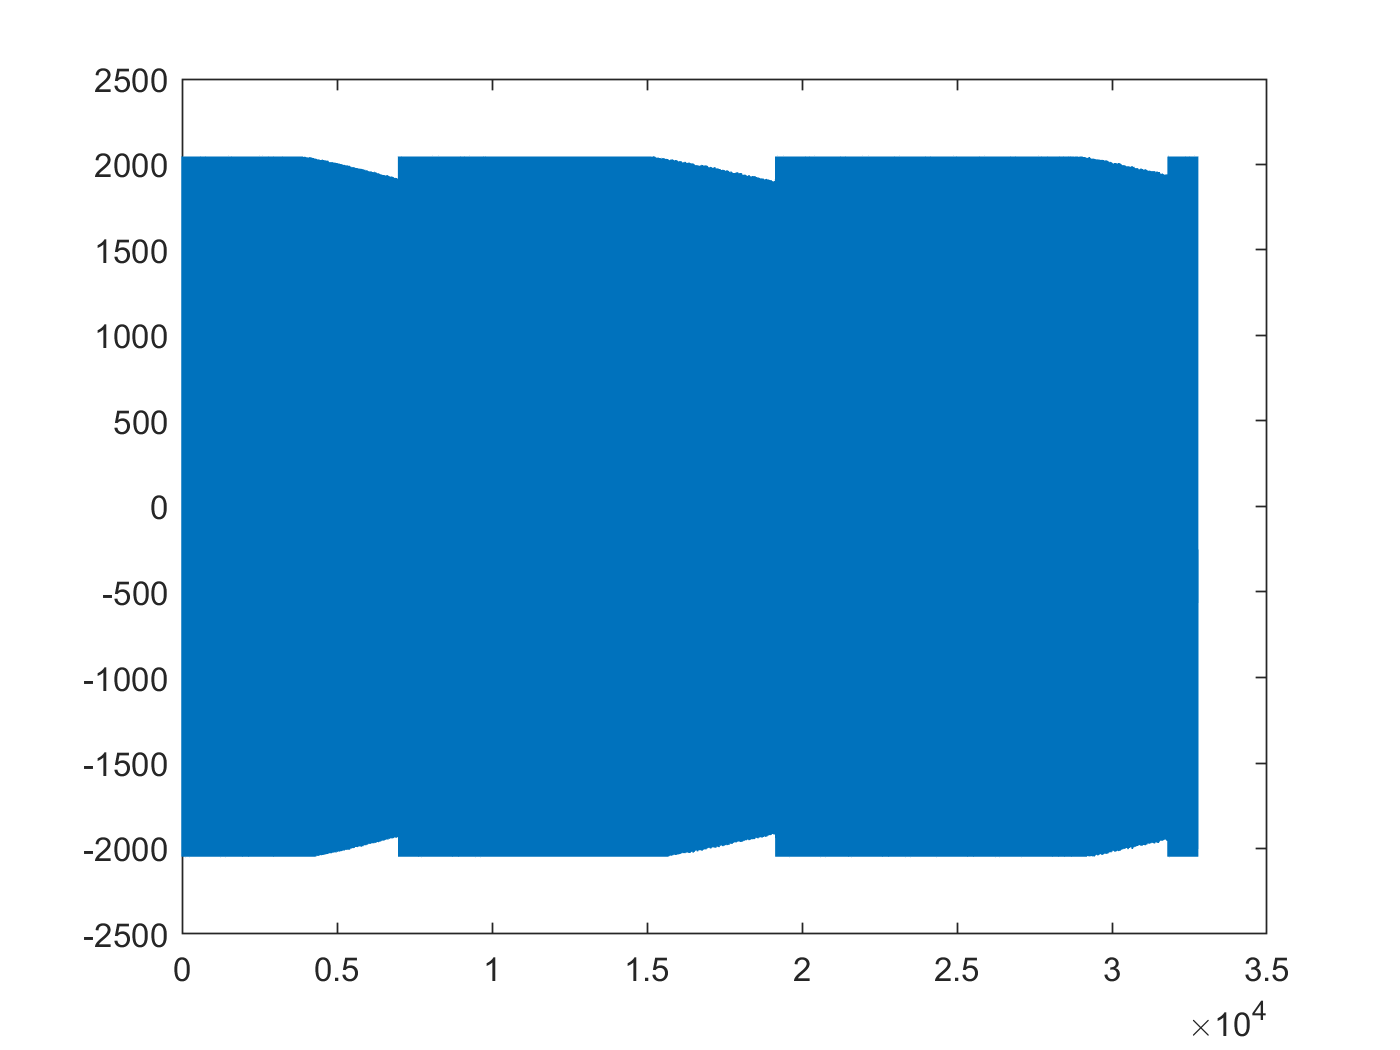

figure; plot(0:2^15-1, real(y));

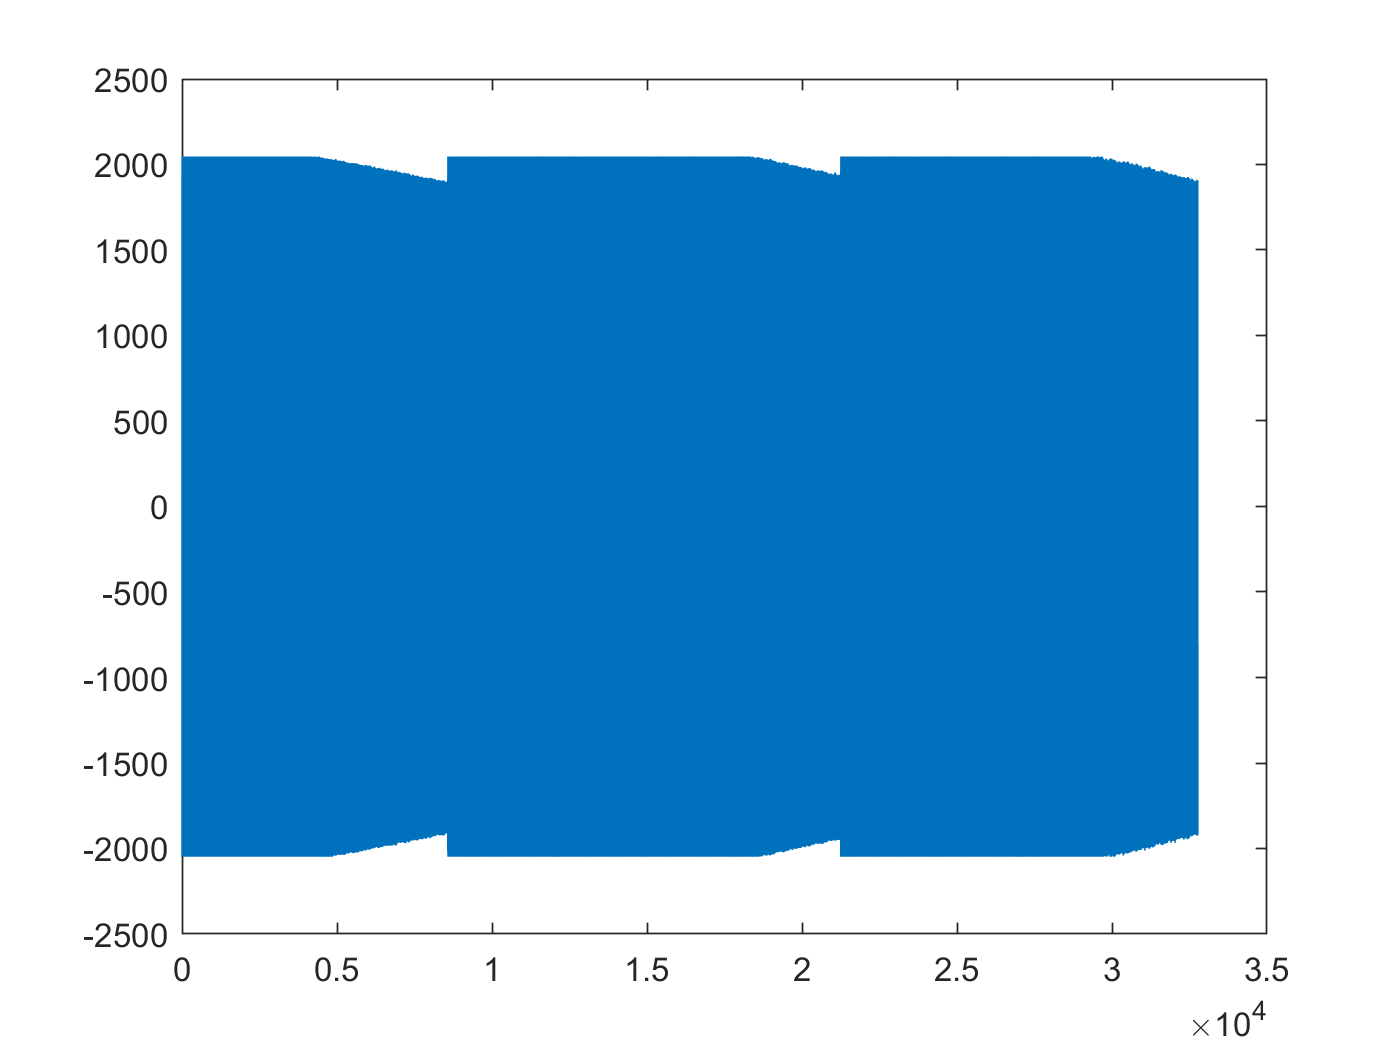

for n = 1:20
    valid = false;
    while ~valid
        [y, valid] = plutoRx();
    end
end
figure; plot(0:2^15-1, real(y));